%Rigt is X (center toward lock button)
%up is Y (center toward camera)
%Front is Z (center toward mobile screen)
load('/home/hazem/MATLAB-Drive/MobileSensorData/sensorlog_Seq69.mat');

% Accessing acceleration data
ax = Acceleration.X;
ay = Acceleration.Y;
az = Acceleration.Z;
accelTime = Acceleration.Timestamp;
acc_measured = [ax, ay, az];
% Accessing Angular Velocity data
wx = AngularVelocity.X;
wy = AngularVelocity.Y;
wz = AngularVelocity.Z;
angVeltime = AngularVelocity.Timestamp;
av_measured = [wx, wy, wz];

avt = seconds(diff(AngularVelocity.Timestamp));
at = seconds(diff(Acceleration.Timestamp)); 
sizeAccel = length(ax);
sizeAngVel = length(wx);

%Synchronization
% Determine the later first reading
laterFirstReading = max(accelTime(1), angVeltime(1));
% Determine the earlier last reading
earlierLastReading = min(accelTime(sizeAccel), angVeltime(sizeAngVel));


% Filter timestamps to include only values within the specified range
accelTime_filtered = accelTime(accelTime >= laterFirstReading & accelTime <= earlierLastReading);
angVelTime_filtered = angVeltime(angVeltime >= laterFirstReading & angVeltime <= earlierLastReading);


commonTime = union(accelTime_filtered, angVelTime_filtered); % Creates a common timeline
% Interpolate acceleration data
accelX_sync = interp1(accelTime, ax, commonTime, 'linear', 'extrap');
accelY_sync = interp1(accelTime, ay, commonTime, 'linear', 'extrap');
accelZ_sync = interp1(accelTime, az, commonTime, 'linear', 'extrap');

% Interpolate angular velocity data
angVelX_sync = interp1(angVeltime, wx, commonTime, 'linear', 'extrap');
angVelY_sync = interp1(angVeltime, wy, commonTime, 'linear', 'extrap');
angVelZ_sync = interp1(angVeltime, wz, commonTime, 'linear', 'extrap');

% Create a synchronized dataset
synchronizedData = struct();
synchronizedData.timestamp = commonTime;
synchronizedData.acceleration = [accelX_sync, accelY_sync, accelZ_sync];
synchronizedData.angular_velocity = [angVelX_sync, angVelY_sync, angVelZ_sync];
commonDT = seconds(diff(commonTime));

%Removing acceleration Bias
calibFrames = 1000;
accBias = [mean(synchronizedData.acceleration(1:calibFrames,1))    mean(synchronizedData.acceleration(1:calibFrames,2))    (mean(synchronizedData.acceleration(1:calibFrames,3)) - 9.81)];
synchronizedData.acceleration = synchronizedData.acceleration - accBias;
gyroBias = [mean(synchronizedData.angular_velocity(1:calibFrames,1))   mean(synchronizedData.angular_velocity(1:calibFrames,2))   mean(synchronizedData.angular_velocity(1:calibFrames,3))];
synchronizedData.angular_velocity = synchronizedData.angular_velocity - gyroBias;


%Filtering noise 
% Sampling frequency and cutoff frequency
fs = 150;  % Sampling frequency (Hz)
fc = 0.01 * fs;  % Cutoff frequency for low-pass filter (1 Hz)

% Design a 2nd-order low-pass Butterworth filter
[b, a] = butter(2, fc / (fs / 2), 'low');  % Low-pass filter

% Apply the filter
%synchronizedData.acceleration = filtfilt(b, a, synchronizedData.acceleration);  % Zero-phase filtering
%synchronizedData.angular_velocity = filtfilt(b, a, synchronizedData.angular_velocity);  % Zero-phase filtering

synchronizedData.acceleration = filtfilt(b, a, synchronizedData.acceleration);  % Zero-phase filtering
synchronizedData.angular_velocity = filtfilt(b, a, synchronizedData.angular_velocity);  % Zero-phase filtering

%{
%using trapezoidal integration
thetaX = cumsum(synchronizedData.angular_velocity(2:end,1) .* commonDT); 
thetaY = cumsum(synchronizedData.angular_velocity(2:end,2) .* commonDT); 
thetaZ = cumsum(synchronizedData.angular_velocity(2:end,3) .* commonDT); 
%}

thetaX = zeros(length(synchronizedData.angular_velocity(2:end,1)),1);
thetaY = zeros(length(synchronizedData.angular_velocity(2:end,2)),1);
thetaZ = zeros(length(synchronizedData.angular_velocity(2:end,3)),1);

for i = 2:length(thetaX)
    % Update velocity (v_i+1 = v_i + a_i * dt)
    
    thetaX(i) = thetaX(i-1) + synchronizedData.angular_velocity(i-1,1) .* commonDT(i);
    thetaY(i) = thetaY(i-1) + synchronizedData.angular_velocity(i-1,2) .* commonDT(i);
    thetaZ(i) = thetaZ(i-1) + synchronizedData.angular_velocity(i-1,3) .* commonDT(i);
end


%{
%Now to get absolute orientation, ie: orientation wrt global coordinated [first frame]
Rglobal = zeros(length(thetaX), 3, 3);
Rglobal(1,:,:) = eye(3);
for i = 2:length(thetaX)
    dyaw = thetaZ(i) - thetaZ(i-1);
    dpitch = thetaY(i) - thetaY(i-1);
    droll = thetaX(i) - thetaX(i-1);
    % Rotation matrices using ZYX order (yaw, pitch, roll)
    dRz = [cos(dyaw) -sin(dyaw) 0;
          sin(dyaw) cos(dyaw) 0;
          0 0 1];

    dRy = [cos(dpitch) 0 sin(dpitch);
          0 1 0;
          -sin(dpitch) 0 cos(dpitch)];

    dRx = [1 0 0;
          0 cos(droll) -sin(droll);
          0 sin(droll) cos(droll)];

    dR = (dRz * dRy * dRx);
    Rglobal(i,:,:) = dR * reshape(Rglobal(i-1,:,:),3,3);
end
%}

%{
% Initialize time step and data

% Pre-allocate rotation matrix for each frame (3x3 rotation matrix per frame)
Rglobal = zeros(length(thetaX), 3, 3); % 3x3 matrix for each frame

% Initialize first frame as the global frame
Rglobal(1, :, :) = eye(3); % First frame is the global reference

% Initialize angles
roll = 0; pitch = 0; yaw = 0; % Assuming initial angles are zero

% Iterate through each frame to calculate orientation
for t = 2:length(thetaX)
    % Integrate gyroscope data to get angular displacement (Euler angles)
    delta_angle = synchronizedData.angular_velocity(t-1,:) * commonDT(t); % Delta angles in rad/sec

    % Update roll, pitch, and yaw
    roll = thetaX(t) + thetaX(1);   % X-axis rotation
    pitch = thetaY(t) + thetaY(1); % Y-axis rotation
    yaw = thetaZ(t) + thetaY(1);     % Z-axis rotation

    % Construct rotation matrices for each angle
    R_roll = [1, 0, 0; 0, cos(roll), -sin(roll); 0, sin(roll), cos(roll)];
    R_pitch = [cos(pitch), 0, sin(pitch); 0, 1, 0; -sin(pitch), 0, cos(pitch)];
    R_yaw = [cos(yaw), -sin(yaw), 0; sin(yaw), cos(yaw), 0; 0, 0, 1];

    % Combined rotation matrix for this frame relative to the first frame
    Rglobal(t, :, :) = (R_roll * R_pitch * R_yaw);
end
%}


AccGlobal = zeros(length(thetaX),3);
AngVelGlobal = zeros(length(thetaX),3);
Orientation = zeros(length(thetaX),3);
gravAcc = zeros(length(thetaX),3);
%Initialize data
% Transform accelerometer data for each frame
for t = 1:length(thetaX)
    % Convert quaternion to rotation matrix
    R_t = quat2rotm(quats(t));  % Rotation matrix from quaternion
    
    % Transform local accelerometer data to global frame
    AccGlobal(i,:) = (R_t * synchronizedData.acceleration(i,:)');
    AngVelGlobal(i,:) = (R_t * synchronizedData.angular_velocity(i,:)');
    Orientation(i,:) = (R_t * [thetaX(i) thetaY(i) thetaZ(i)]');
end


%{
%Referencing data to global frame
AccGlobal = zeros(length(thetaX),3);
AngVelGlobal = zeros(length(thetaX),3);
Orientation = zeros(length(thetaX),3);
gravAcc = zeros(length(thetaX),3);
%Initialize data

AccGlobal(1,:) = synchronizedData.acceleration(1,:);
AngVelGlobal(1,:) = synchronizedData.angular_velocity(1,:);
Orientation(1,:) = [thetaX(1) thetaY(1) thetaZ(1)]';
gravAcc(1,:) = [0 0 9.81];
for i = 2:length(thetaX)
    AccGlobal(i,:) = (reshape(Rglobal(i,:,:),3,3) * synchronizedData.acceleration(i,:)') - (reshape(Rglobal(i,:,:),3,3) * gravAcc(1,:)');
    AngVelGlobal(i,:) = (reshape(Rglobal(i,:,:),3,3) * synchronizedData.angular_velocity(i,:)');
    Orientation(i,:) = (reshape(Rglobal(i,:,:),3,3) * [thetaX(i) thetaY(i) thetaZ(i)]');
end
%}

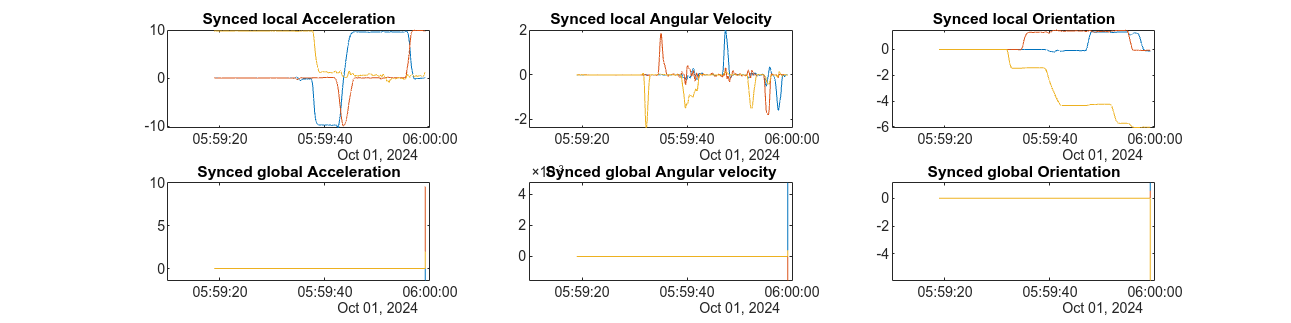

figure('Position', [800, 0, 3200, 800]);
subplot(2, 3, 1);
plot(commonTime,synchronizedData.acceleration(:,1));
hold on;
plot(commonTime,synchronizedData.acceleration(:,2));
plot(commonTime,synchronizedData.acceleration(:,3));
hold off;
%legend("synced A_x local", "synced A_y local", "synced A_z local");
title("Synced local Acceleration")

subplot(2, 3, 2);
plot(commonTime,synchronizedData.angular_velocity(:,1));
hold on;
plot(commonTime,synchronizedData.angular_velocity(:,2));
plot(commonTime,synchronizedData.angular_velocity(:,3));
hold off;
%legend("synced w_x local", "synced w_y local", "synced w_z local");
title("Synced local Angular Velocity")

subplot(2, 3, 3);
plot(commonTime(2:end),thetaX);
hold on;
plot(commonTime(2:end),thetaY);
plot(commonTime(2:end),thetaZ);
hold off;
%legend("theta_x local", "theta_y local", "theta_z local")
title("Synced local Orientation")

subplot(2, 3, 4);
plot(commonTime(2:end),AccGlobal(:,1));
hold on;
plot(commonTime(2:end),AccGlobal(:,2));
plot(commonTime(2:end),AccGlobal(:,3));
hold off;
%legend("A_x global", "A_y global", "A_z global")
title("Synced global Acceleration")

subplot(2, 3, 5);
plot(commonTime(2:end),AngVelGlobal(:,1));
hold on;
plot(commonTime(2:end),AngVelGlobal(:,2));
plot(commonTime(2:end),AngVelGlobal(:,3));
hold off;
%legend("w_x global", "w_y global", "w_z global")
title("Synced global Angular velocity")

subplot(2, 3, 6);
plot(commonTime(2:end),Orientation(:,1));
hold on;
plot(commonTime(2:end),Orientation(:,2));
plot(commonTime(2:end),Orientation(:,3));
hold off;
%legend("theta_x global", "theta_y global", "theta_z global")
title("Synced global Orientation")

%global acceleration
%gravAccGlobal = synchronizedData.acceleration(1,:);
%gravAccGlobal = [0 0 9.81];
%motion_acceleration = (AccGlobal - gravAccGlobal);
%motion_acceleration = motion_acceleration - accBias;
motion_acceleration = AccGlobal;

%{
%Filtering noise 
% Sampling frequency and cutoff frequency
fs = 150;  % Sampling frequency (Hz)
fc = 0.0001 * fs;  % Cutoff frequency for low-pass filter (1 Hz)

% Design a 2nd-order low-pass Butterworth filter
[b, a] = butter(2, fc / (fs / 2), 'high');  % Low-pass filter

% Apply the filter
%synchronizedData.acceleration = filtfilt(b, a, synchronizedData.acceleration);  % Zero-phase filtering
%synchronizedData.angular_velocity = filtfilt(b, a, synchronizedData.angular_velocity);  % Zero-phase filtering

motion_acceleration = filtfilt(b, a, motion_acceleration);  % Zero-phase filtering
%}

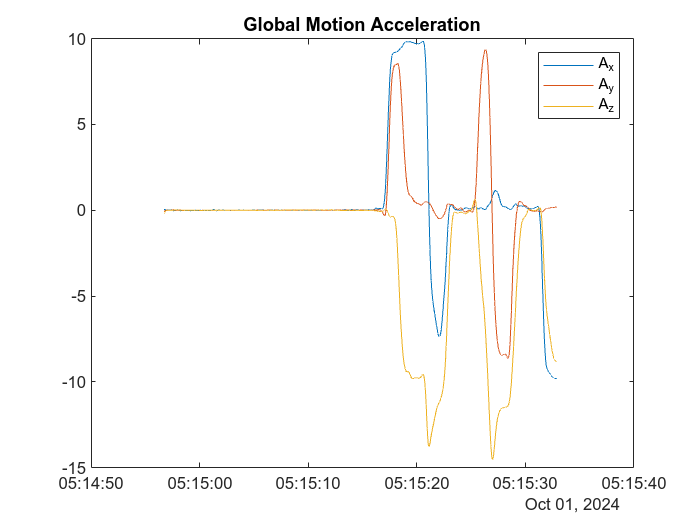

figure;
plot(commonTime(2:end),motion_acceleration(:,1));
hold on;
plot(commonTime(2:end),motion_acceleration(:,2));
plot(commonTime(2:end),motion_acceleration(:,3));
hold off;
legend("A_x", "A_y", "A_z");
title("Global Motion Acceleration")



%Using discrete integration
velGlobal = zeros(size(motion_acceleration));
posGlobal = zeros(size(motion_acceleration));
%{
threshold = 0.1;  % Define a threshold for low accelerations
window_size = 10;
% Apply moving average filter to accelerometer and gyroscope data
motion_acceleration(:, 1) = movmean(motion_acceleration(:, 1), window_size);
motion_acceleration(:, 2) = movmean(motion_acceleration(:, 2), window_size);
motion_acceleration(:, 3) = movmean(motion_acceleration(:, 3), window_size);

synchronizedData.acceleration(:,1) = movmean(synchronizedData.acceleration(:,1), window_size);
synchronizedData.acceleration(:,2) = movmean(synchronizedData.acceleration(:,2), window_size);
synchronizedData.acceleration(:,3) = movmean(synchronizedData.acceleration(:,3), window_size);

%}

for i = 2:length(thetaX)
    % Update velocity (v_i+1 = v_i + a_i * dt)
    
    velGlobal(i,:) = velGlobal(i-1, :) + (motion_acceleration(i-1, :) .* commonDT(i));
    
    %{
    if norm(motion_acceleration(i,1)) < threshold
        velGlobal(i,1) = 0;  % Reset velocity to zero during stationary periods
    end
    if norm(motion_acceleration(i,2)) < threshold
        velGlobal(i,2) = 0;  % Reset velocity to zero during stationary periods
    end
    if norm(motion_acceleration(i,3)) < threshold
        velGlobal(i,3) = 0;  % Reset velocity to zero during stationary periods
    end
    %}
    % Update position (x_i+1 = x_i + v_i * dt)
    posGlobal(i,:) = posGlobal(i-1,:) + (velGlobal(i-1,:) .* commonDT(i));
end


% Integrate acceleration to get velocity using cumtrapz
%velocity_x = cumtrapz(0.001,motion_acceleration(:, 1)); % Velocity along x-axis
%velocity_y = cumtrapz(0.001,motion_acceleration(:, 2)); % Velocity along y-axis
%velocity_z = cumtrapz(0.001,motion_acceleration(:, 3)); % Velocity along z-axis
%velGlobal = [velocity_x velocity_y velocity_x];
% Detect zero velocity (ZUPT)

%velGlobal = cumtrapz(commonDT, motion_acceleration);
% Integrate velocity to get position
%position_x = cumtrapz(0.001,velGlobal(:, 1)); % Position along x-axis
%position_y = cumtrapz(0.001,velGlobal(:, 2)); % Position along y-axis
%position_z = cumtrapz(0.001,velGlobal(:, 3)); % Position along z-axis
%posGlobal = [position_x position_y position_z];
%posGlobal = cumtrapz(commonDT, velGlobal);

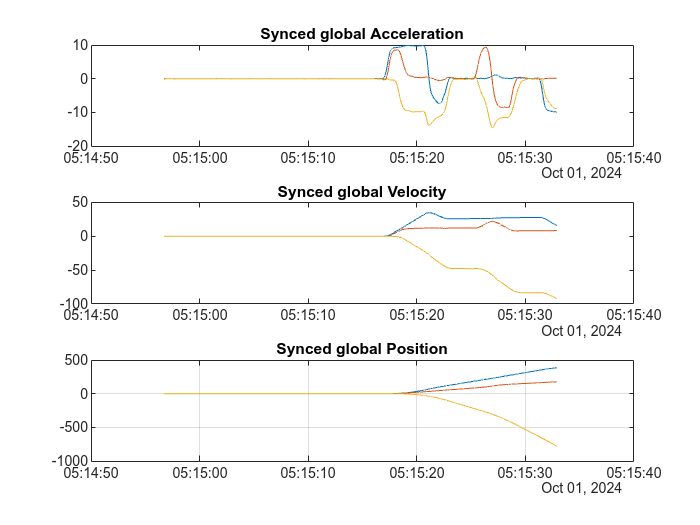

figure;
subplot(3, 1, 1);
plot(commonTime(2:end),motion_acceleration(:,1));
hold on;
plot(commonTime(2:end),motion_acceleration(:,2));
plot(commonTime(2:end),motion_acceleration(:,3));
hold off;
%legend("A_x global", "A_y global", "A_z global")
title("Synced global Acceleration")

subplot(3, 1, 2);
plot(commonTime(2:end),velGlobal(:,1));
hold on;
plot(commonTime(2:end),velGlobal(:,2));
plot(commonTime(2:end),velGlobal(:,3));
hold off;
%legend("V_x global", "V_y global", "V_z global")
title("Synced global Velocity")

subplot(3, 1, 3);
plot(commonTime(2:end),posGlobal(:,1));
hold on;
plot(commonTime(2:end),posGlobal(:,2));
plot(commonTime(2:end),posGlobal(:,3));
hold off;
%legend("P_x global", "P_y global", "P_z global")
title("Synced global Position")

grid on;

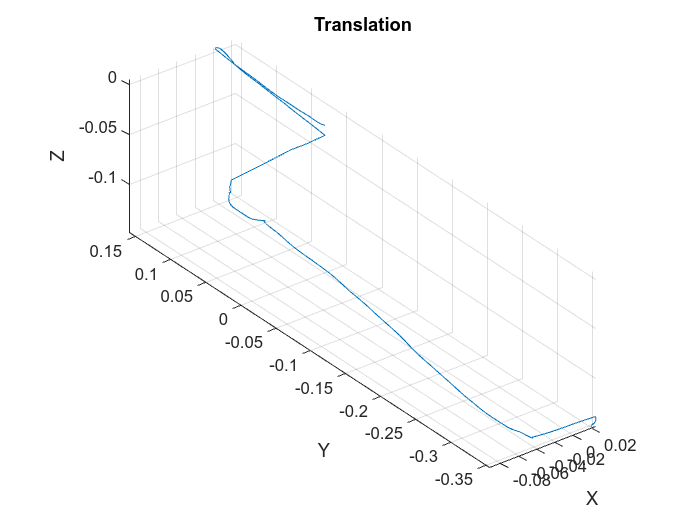

figure;
plot3(posGlobal(:,1), posGlobal(:,2), posGlobal(:,3));
xlabel('X'); ylabel('Y'); zlabel('Z');
axis equal;
title('Translation');
grid on;

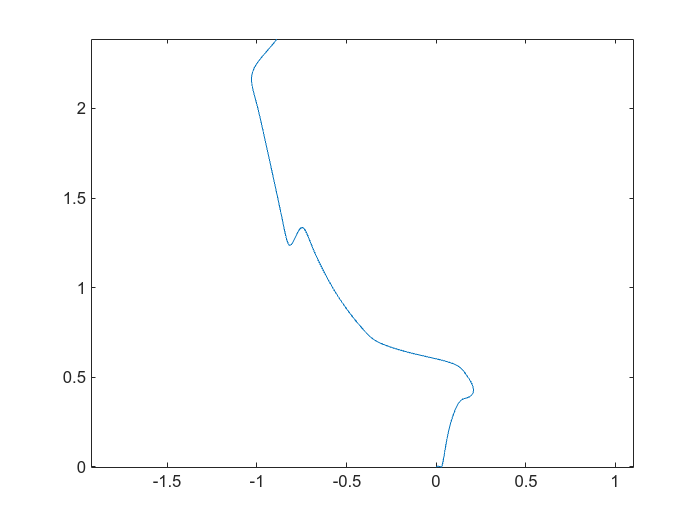

figure;
plot(posGlobal(:,1),posGlobal(:,2))
axis equal;

detAcc = detrend(motion_acceleration);
detVel = detrend(velGlobal);
fillOutAcc = filloutliers(motion_acceleration,"center");
remOutAcc = hampel(motion_acceleration);

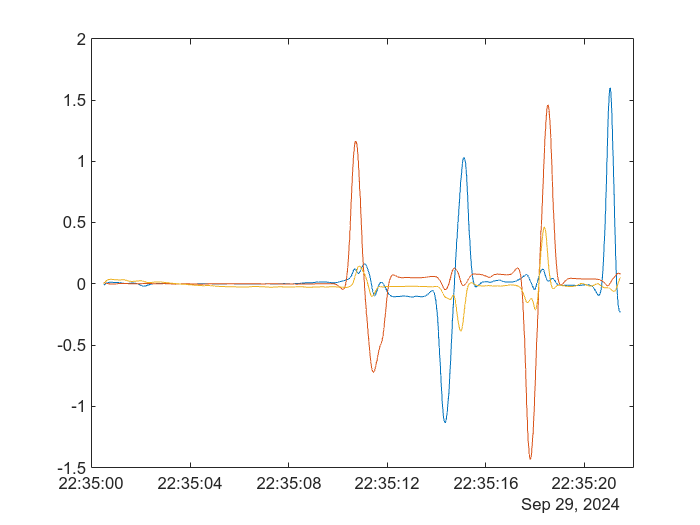

figure;
plot(commonTime(2:end), motion_acceleration)